# Publication Neural-Activity Panels

Loads self-contained publication-analysis files, prepares reusable panel data, and creates six publication figures plus an editable combined layout.

clear; clc; close all;
repo_root = project_root();
add_project_paths(repo_root);

## Configuration

cfg = struct();
cfg.preferred_backend = 'gpu';
cfg.display_seed = 3;
cfg.required_panel6_seeds = 3;
cfg.lorenz_warmup_s = 5;
cfg.lorenz_display_s = 5;
cfg.voltage_neurons = 3;
cfg.lorenz_voltage_rate_quantiles = [0.4 .7 .97];
cfg.static_voltage_rate_quantiles = [0.7 .8 0.98];
cfg.static_examples = 3;
cfg.static_voltage_x_limit_s = .9;
cfg.raster_neuron_count = 500;
cfg.raster_neuron_seed = 20260714;
cfg.raster_marker_size = 3;
cfg.sample_window_face_alpha = .14;
cfg.trace_min_gap_mV = 12;
cfg.voltage_spike_height_mV = 70;
cfg.font_name = 'Arial';
cfg.font_size = 10;
cfg.tick_font_size = cfg.font_size;
cfg.title_font_size = [];
cfg.axis_label_font_size = [];
cfg.colorbar_label_font_size = [];
cfg.voltage_window_label_font_size = cfg.font_size - 1;
cfg.voltage_window_label_clearance_fraction = .05;
cfg.voltage_window_label_horizontal_offset_fraction = -.06;
cfg.legend_font_size = cfg.font_size - 2;
cfg.lorenz_legend_downshift_pixels = 14;
cfg.line_width = 1.15;
cfg.identity_line_width = .9;
cfg.scatter_marker_size = 4;
cfg.summary_median_line_width = 1.2;
cfg.summary_errorbar_line_width = 1.1;
cfg.summary_point_marker_size = 5;
cfg.combined_panel_labels = {'A','B','C','D','E','F'};
cfg.combined_panel_label_font_size = cfg.font_size + 4;
cfg.combined_panel_label_offset = [.004 .028];
cfg.combined_panel_label_size = [.03 .022];
cfg.car_price_scale = 1000;
cfg.car_price_correlation_position = [.04 .92];
cfg.car_price_correlation_font_size = [];
cfg.violin_max_width = .32;
cfg.violin_face_alpha = .88;
cfg.rate_distribution_y_scale = 'log';
cfg.three_row_top_axes_position = [.15 .78 .75 .14];
cfg.three_row_middle_axes_position = [.15 .42 .75 .14];
cfg.three_row_bottom_axes_position = [.15 .07 .75 .14];
cfg.summary_axes_position = [.15 .12 .75 .78];
cfg.mnist_confusion_axes_position = [.15 .69 .70 .26];
cfg.mnist_confusion_scale_axes_position = [.865 .69 .035 .26];
cfg.mnist_raster_axes_position = [.15 .38 .75 .14];
cfg.mnist_voltage_axes_position = [.15 .07 .75 .14];
cfg.export_combined_figure = true;
cfg.combined_export_dpi = 500;
cfg.combined_export_filename = 'publication_neural_activity_panels_500dpi.png';
cfg.combined_export_svg_filename = 'publication_neural_activity_panels.svg';
cfg.figure_sizes = struct('lorenz',[7.2 5.8], 'car_price',[6.8 6.1], ...
    'mnist',[6.8 6.4], 'distribution',[8.8 3.6], 'active_fraction',[8.8 3.6], ...
    'combined',[210/25.4 297/25.4]);
cfg.combined_export_height_inches = cfg.figure_sizes.combined(2);
cfg.combined_export_aspect_ratio = cfg.figure_sizes.combined(1) / cfg.figure_sizes.combined(2);
cfg.text = panel_text();
cfg.cache_version = 14;
cfg.force_rebuild = false;
cfg.colors = panel_colors();

analysis_dir = fullfile(repo_root, 'outputs', 'publication_analysis');
output_dir = fullfile(repo_root, 'shared', 'plotting', 'publication_figures', 'generated_neural_activity_panels');
cache_dir = fullfile(output_dir, 'cache');
if exist(output_dir, 'dir') ~= 7, mkdir(output_dir); end
if exist(cache_dir, 'dir') ~= 7, mkdir(cache_dir); end

## Load and prepare data

[analyses, source_files] = load_required_analyses(analysis_dir, cfg);
cache_file = fullfile(cache_dir, 'publication_neural_activity_panel_data.mat');
panel_data = load_or_build_panel_data(cache_file, analyses, source_files, cfg);

## Plot

figures = gobjects(1, 6);
fprintf('[publication panels] Plotting Lorenz panel...\n');

[publication panels] Plotting Lorenz panel...


figures(1) = plot_lorenz_panel(panel_data.lorenz, cfg);
fprintf('[publication panels] Plotting car-price panel...\n');

[publication panels] Plotting car-price panel...


figures(2) = plot_car_price_panel(panel_data.car_price, cfg);
fprintf('[publication panels] Plotting MNIST panel...\n');

[publication panels] Plotting MNIST panel...


figures(3) = plot_mnist_panel(panel_data.mnist, cfg);

@author : slandarer
@author : slandarer


fprintf('[publication panels] Plotting learned-bias violin panel...\n');

[publication panels] Plotting learned-bias violin panel...


figures(4) = plot_distribution_panel(panel_data.summary.bias, panel_data.summary.labels, ...
    cfg.text.bias_distribution_ylabel, cfg.text.bias_distribution_title, cfg.colors.bias, cfg, 'linear');
fprintf('[publication panels] Plotting firing-rate violin panel...\n');

[publication panels] Plotting firing-rate violin panel...


figures(5) = plot_distribution_panel(panel_data.summary.rate, panel_data.summary.labels, ...
    cfg.text.rate_distribution_ylabel, cfg.text.rate_distribution_title, cfg.colors.rate, cfg, cfg.rate_distribution_y_scale);
fprintf('[publication panels] Plotting active-neuron panel...\n');

[publication panels] Plotting active-neuron panel...


figures(6) = plot_active_fraction_panel(panel_data.summary, cfg);
fprintf('[publication panels] Plotting combined publication figure...\n');

[publication panels] Plotting combined publication figure...


combined_figure = combine_panel_figures(panel_data, cfg);

@author : slandarer
@author : slandarer


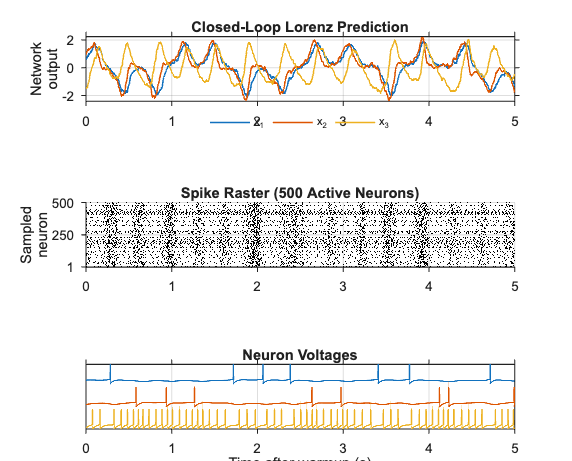

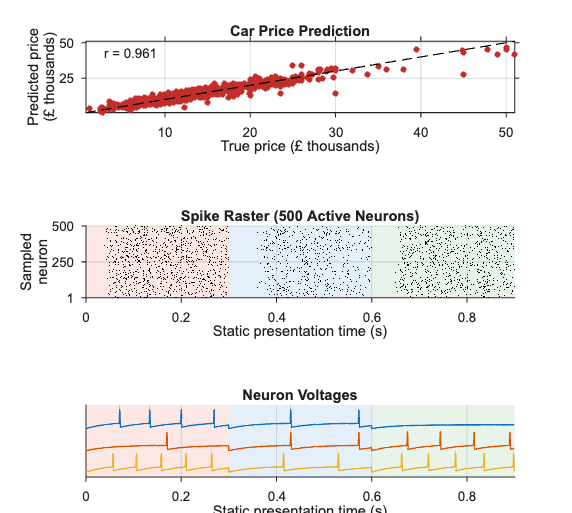

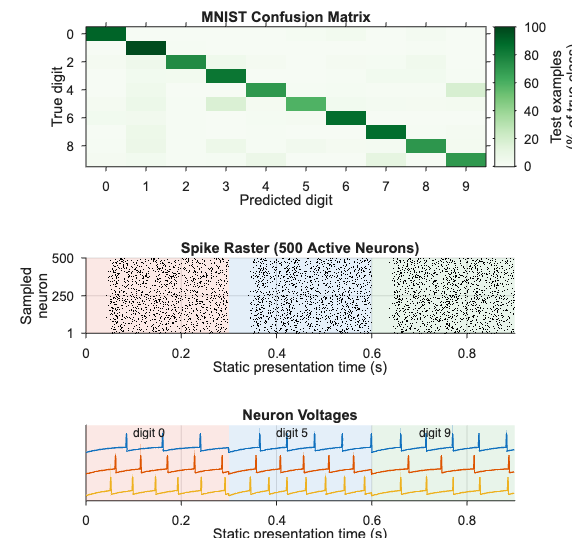

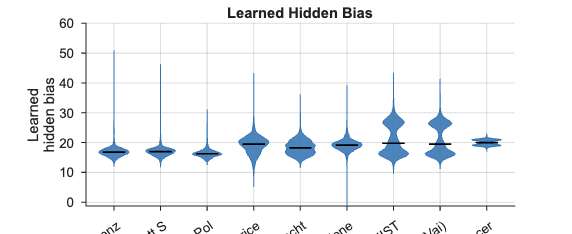

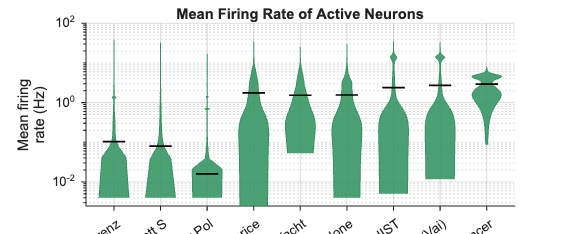

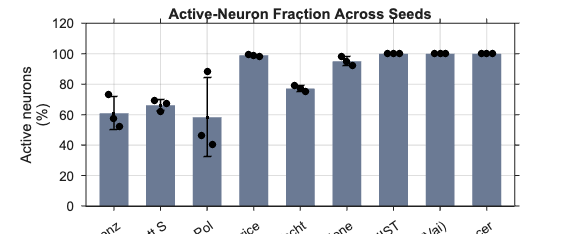

hide_axes_toolbars([figures(:); combined_figure]);

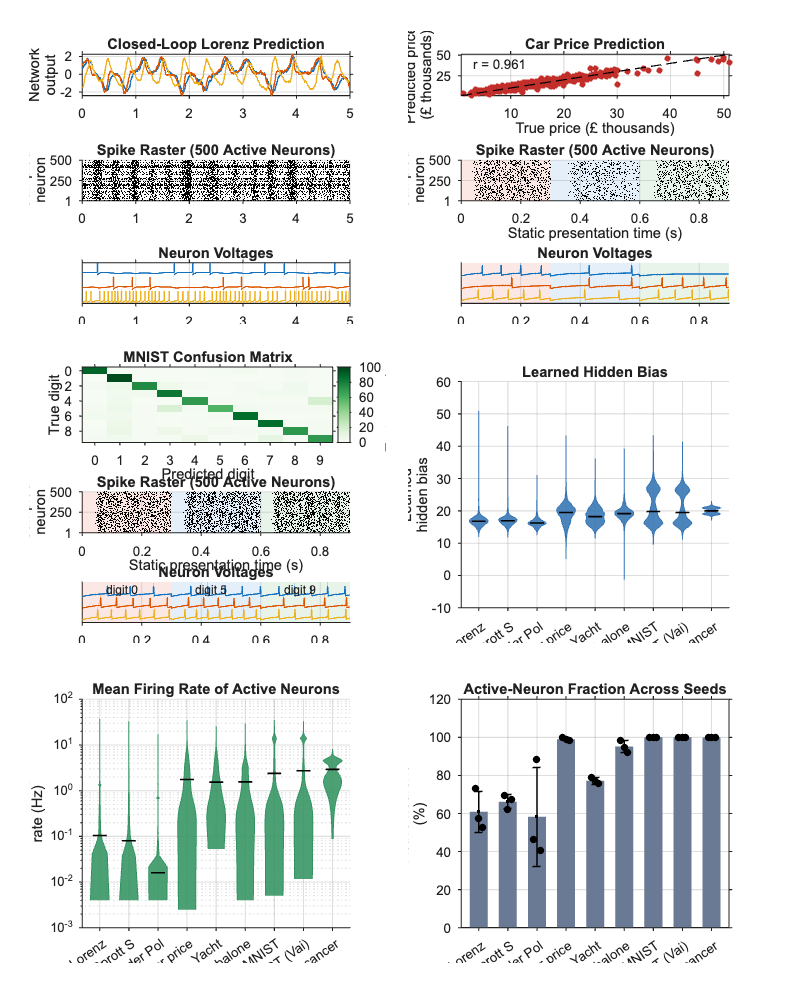

[publication panels] Exported combined figure at 500 DPI.


[publication panels] Exported combined figure as SVG.


if cfg.export_combined_figure
    export_file = fullfile(output_dir,cfg.combined_export_filename);
    export_combined_figure(combined_figure,export_file,cfg.combined_export_dpi, ...
        cfg.combined_export_height_inches,cfg.combined_export_aspect_ratio,'png');
    export_file = fullfile(output_dir,cfg.combined_export_svg_filename);
    export_combined_figure(combined_figure,export_file,[], ...
        cfg.combined_export_height_inches,cfg.combined_export_aspect_ratio,'svg');
end


fprintf('Generated six neural-activity figures and one combined publication figure.\n');

Generated six neural-activity figures and one combined publication figure.


## Combined-Figure Export

The combined figure is exported automatically at the configured DPI.

function [analyses, source_files] = load_required_analyses(analysis_dir, cfg)
specs = task_specs();
analyses = cell(1, numel(specs));
source_files = cell(1, numel(specs));
for ii = 1:numel(specs)
    file = newest_analysis_file(analysis_dir, specs(ii).task_id, cfg.preferred_backend);
    if isempty(file)
        error('publication_panels:missingAnalysis', ...
            'No readable publication analysis was found for %s.', specs(ii).label);
    end
    A = load_publication_analysis_file(file);
    validate_analysis(A, specs(ii));
    analyses{ii} = A;
    source_files{ii} = file;
end
end

function specs = task_specs()
specs = struct('field', {}, 'task_id', {}, 'label', {});
specs(end+1) = struct('field','lorenz','task_id','dynamical_systems_lorenz','label','Lorenz');
specs(end+1) = struct('field','sprotts','task_id','dynamical_systems_sprotts','label','Sprott S');
specs(end+1) = struct('field','vanderpol','task_id','dynamical_systems_vanderpol','label','Van der Pol');
specs(end+1) = struct('field','car_price','task_id','regression_toyota','label','Car price');
specs(end+1) = struct('field','yacht','task_id','regression_yacht','label','Yacht');
specs(end+1) = struct('field','abalone','task_id','regression_abalone','label','Abalone');
specs(end+1) = struct('field','mnist','task_id','classification_MNIST','label','MNIST');
specs(end+1) = struct('field','afromnist','task_id','classification_AfroMNIST_Vai','label','Afro-MNIST (Vai)');
specs(end+1) = struct('field','bc','task_id','classification_BC','label','Breast cancer');
end

function file = newest_analysis_file(folder, task_id, preferred_backend)
file = '';
backends = {preferred_backend, 'cpu'};
backends = unique(backends, 'stable');
for bb = 1:numel(backends)
    files = dir(fullfile(folder, sprintf('%s_%s_test_analysis_*.mat', task_id, backends{bb})));
    [~, order] = sort([files.datenum], 'descend');
    for kk = order
        candidate = fullfile(files(kk).folder, files(kk).name);
        try
            variables = whos('-file', candidate);
            if any(strcmp({variables.name}, 'analysis'))
                file = candidate;
                return;
            end
        catch
        end
    end
end
end

function validate_analysis(A, spec)
required = {'task_id','seeds'};
for ii = 1:numel(required)
    if ~isfield(A, required{ii})
        error('publication_panels:invalidAnalysis', '%s analysis lacks %s.', spec.label, required{ii});
    end
end
if ~strcmp(char(A.task_id), spec.task_id) || isempty(A.seeds)
    error('publication_panels:invalidAnalysis', 'Invalid or empty analysis for %s.', spec.label);
end
for ii = 1:numel(A.seeds)
    seed = A.seeds(ii);
    needed = {'model','options','bias','test','neural_activity'};
    if ~all(isfield(seed, needed))
        error('publication_panels:invalidSeed', '%s seed %d lacks required saved data.', spec.label, ii);
    end
end
end

function data = load_or_build_panel_data(cache_file, analyses, source_files, cfg)
voltage_selection_config = voltage_selection_cache_config(cfg);
if ~cfg.force_rebuild && exist(cache_file, 'file') == 2
    C = load(cache_file, 'panel_data');
    if isfield(C, 'panel_data') && isscalar(C.panel_data) && ...
            isfield(C.panel_data, 'cache_version') && C.panel_data.cache_version == cfg.cache_version && ...
            isfield(C.panel_data, 'source_files') && isequal(C.panel_data.source_files, source_files) && ...
            isfield(C.panel_data, 'voltage_selection_config') && ...
            isequal(C.panel_data.voltage_selection_config, voltage_selection_config)
        data = C.panel_data;
        return;
    end
end
specs = task_specs();
index = struct();
for ii = 1:numel(specs), index.(specs(ii).field) = ii; end
data = struct();
data.lorenz = build_lorenz_data(analyses{index.lorenz}, cfg);
data.car_price = build_car_price_data(analyses{index.car_price}, cfg);
data.mnist = build_mnist_data(analyses{index.mnist}, cfg);
data.summary = build_summary_data(analyses, specs, cfg);
data.cache_version = cfg.cache_version;
data.source_files = source_files;
data.voltage_selection_config = voltage_selection_config;
panel_data = data; %#ok<NASGU>
save(cache_file, 'panel_data', '-v7.3');
end

function cache_config = voltage_selection_cache_config(cfg)
% These fields determine the rate ranking and voltage traces saved in cache.
cache_config = struct();
cache_config.display_seed = double(cfg.display_seed);
cache_config.lorenz_warmup_s = double(cfg.lorenz_warmup_s);
cache_config.lorenz_display_s = double(cfg.lorenz_display_s);
cache_config.lorenz_voltage_rate_quantiles = double(cfg.lorenz_voltage_rate_quantiles(:).');
cache_config.static_voltage_rate_quantiles = double(cfg.static_voltage_rate_quantiles(:).');
cache_config.static_examples = double(cfg.static_examples);
cache_config.voltage_spike_height_mV = double(cfg.voltage_spike_height_mV);
cache_config.trace_min_gap_mV = double(cfg.trace_min_gap_mV);
end

function seed = select_seed(A, requested)
values = arrayfun(@(x) double(x.init_seed), A.seeds);
index = find(values == requested, 1);
if isempty(index)
    error('publication_panels:missingRequestedSeed', ...
        'The requested display seed %d is unavailable. Available seeds: %s.', ...
        requested,number_list(values));
end
seed = A.seeds(index);
if ~isscalar(seed)
    error('publication_panels:seedNotScalar', 'Selected seed data must be scalar.');
end
end

function data = build_lorenz_data(A, cfg)
seed = select_seed(A, cfg.display_seed);
P = prepared_model(seed);
events = seed.spike_events;
if ~isstruct(events) || ~isfield(events,'status') || ~strcmp(char(events.status),'ok') || isempty(events.events_by_ic)
    error('publication_panels:missingEvents', 'Lorenz analysis lacks saved spike events.');
end
dt = double(events.dt);
warmup_steps = double(events.closed_loop_warmup_steps);
if warmup_steps ~= round(cfg.lorenz_warmup_s / dt)
    error('publication_panels:warmupMismatch', 'Configured and saved Lorenz warmups differ.');
end
panel_steps = round(cfg.lorenz_display_s / dt);
event = events.events_by_ic(1);
if double(event.n_steps) < warmup_steps + panel_steps
    error('publication_panels:shortEvents', 'Saved Lorenz events are shorter than the requested panel.');
end
first_step = warmup_steps + 1;
panel_rates = event_rates(event, first_step, panel_steps, P.N_hidden, dt);
neurons = select_spiking_rate_quantiles(panel_rates, cfg.lorenz_voltage_rate_quantiles);
[U, spikes] = replay_lorenz_voltage(seed, P, neurons, panel_steps, cfg);
if any(sum(spikes,2) == 0), error('publication_panels:missingDisplayedSpike', 'A Lorenz example neuron did not spike.'); end
U = add_display_spike_peaks(U, spikes, resting_plus_spike_height(P, neurons, cfg.voltage_spike_height_mV));
prediction = first_prediction(seed.test);
if size(prediction,1) < panel_steps, error('publication_panels:shortPrediction','Saved Lorenz prediction is too short.'); end
data = struct();
data.t = (0:panel_steps-1).' .* dt;
data.prediction = double(prediction(1:panel_steps,:));
data.raster = event_spike_raster(event, first_step, panel_steps, P.N_hidden, dt, cfg);
data.voltage = offset_traces(U, cfg.trace_min_gap_mV);
data.neurons = neurons;
data.neuron_rates = panel_rates(neurons);
end

function P = prepared_model(seed)
P = seed.model;
P = ensure_model_architecture_fields(P, seed.options);
P.B = single(seed.bias(:));
end

function prediction = first_prediction(test)
if isfield(test,'pred_norm_by_ic') && ~isempty(test.pred_norm_by_ic)
    prediction = test.pred_norm_by_ic{1};
elseif isfield(test,'pred_norm')
    prediction = test.pred_norm;
else
    error('publication_panels:missingPrediction','Saved test output is unavailable.');
end
end

function rates = event_rates(event, first_step, n_steps, n_hidden, dt)
steps = double(event.event_steps(:));
neurons = double(event.event_neurons(:));
keep = steps >= first_step & steps < first_step+n_steps;
rates = zeros(n_hidden,1);
if any(keep), rates = accumarray(neurons(keep),1,[n_hidden 1],@sum,0); end
rates = rates ./ max(n_steps*dt,eps);
end

function [U, S] = replay_lorenz_voltage(seed, P, neurons, panel_steps, cfg)
opts = seed.options;
opts.T_sim = single(cfg.lorenz_display_s);
opts.closed_loop_warmup_time = single(cfg.lorenz_warmup_s);
opts.closed_loop_validation_ics = 1;
opts.closed_loop_test_ics = 1;
eval_set = make_closed_loop_eval_set(opts);
warmup = eval_set.warmup_steps;
x = eval_set.x_true{1}; lambda = eval_set.lambda{1};
u = single(zeros(P.N_hidden,1)+P.E_L); w = zeros(P.N_hidden,1,'single');
x_syn = zeros(P.N_hidden,1,'single'); r = zeros(P.N_hidden,1,'single'); z = zeros(P.N_out,1,'single');
U = nan(numel(neurons),panel_steps); S = false(numel(neurons),panel_steps);
for k = 1:warmup+panel_steps
    if k == 1 || lambda(k), input = x(:,k); else, input = z; end
    I = P.W_in*(P.INPUT_SCALE*single(input));
    [u,w,~,spike,~,x_syn,r] = primary_step(P,I,u,w,x_syn,r);
    z = P.W_out*r;
    if k > warmup
        q = k-warmup; U(:,q) = double(u(neurons)); S(:,q) = spike(neurons);
    end
end
end

function data = build_car_price_data(A, cfg)
seed = select_seed(A,cfg.display_seed); P = prepared_model(seed);
dataset = load_static_data("regression",seed.options);
require_static_saved_data(seed,size(dataset.X_test,2));
truth = task_units(dataset.Y_test,dataset); prediction = task_units(seed.test.Z,dataset);
[truth_sorted,order] = sort(truth(:));
samples = span_indices(truth,cfg.static_examples);
[voltage,raster] = static_voltage_data(P,dataset.X_test,samples,seed.options,cfg,repmat("",numel(samples),1));
data = struct();
data.truth = double(truth_sorted) ./ cfg.car_price_scale;
data.prediction = double(prediction(order)) ./ cfg.car_price_scale;
data.raster = raster;
data.voltage = voltage;
end

function data = build_mnist_data(A,cfg)
seed = select_seed(A,cfg.display_seed); P = prepared_model(seed);
dataset = load_static_data("classification",seed.options);
require_static_saved_data(seed,size(dataset.X_test,2));
[~,predicted] = max(seed.test.Z,[],1); [~,truth] = max(dataset.Y_test,[],1);
n_class = size(dataset.Y_test,1); examples = first_class_examples(dataset.Y_test,n_class);
chosen_classes = unique(round(linspace(1,n_class,cfg.static_examples)));
[voltage,raster] = static_voltage_data(P,dataset.X_test,examples(chosen_classes),seed.options,cfg,compose('digit %d',chosen_classes-1));
data = struct();
data.confusion = row_percentage_confusion(confusion_matrix(truth,predicted,n_class));
data.labels = compose('%d',0:n_class-1);
data.raster = raster;
data.voltage = voltage;
end

function require_static_saved_data(seed,n_test)
if ~isfield(seed.test,'Z') || isempty(seed.test.Z)
    error('publication_panels:missingStaticOutput','Saved static test output is unavailable.');
end
if ~isfield(seed.neural_activity,'firing_rate_matrix_hz') || ...
        size(seed.neural_activity.firing_rate_matrix_hz,2) ~= n_test
    error('publication_panels:missingStaticRates','Saved full-test firing-rate matrix is unavailable or mismatched.');
end
end

function [voltage,raster] = static_voltage_data(P,X,samples,opts,cfg,labels)
n_samples = numel(samples); steps = double(opts.steps_present);
all_U = cell(1,n_samples); all_S = cell(1,n_samples); total_counts = zeros(P.N_hidden,1);
for ii = 1:n_samples
    [S,U] = static_spike_diagnostics_cpu(P,X(:,samples(ii)),opts);
    S = S(:,:,1); all_S{ii} = S; all_U{ii} = U;
    total_counts = total_counts + sum(S,2);
end
rates = total_counts./max(n_samples*steps*double(opts.dt),eps);
neurons = select_spiking_rate_quantiles(rates,cfg.static_voltage_rate_quantiles);
U = zeros(numel(neurons),n_samples*steps); S = false(numel(neurons),n_samples*steps);
t = zeros(1,n_samples*steps); windows = zeros(n_samples,2);
for ii = 1:n_samples
    idx = (ii-1)*steps+(1:steps);
    U(:,idx) = double(all_U{ii}(neurons,:)); S(:,idx) = all_S{ii}(neurons,:);
    start_t = (ii-1)*steps*double(opts.dt);
    t(idx) = start_t+(0:steps-1)*double(opts.dt);
    windows(ii,:) = [t(idx(1)),t(idx(end))+double(opts.dt)];
end
if any(sum(S,2)==0), error('publication_panels:missingDisplayedSpike','A static example neuron did not spike.'); end
U = add_display_spike_peaks(U,S,resting_plus_spike_height(P,neurons,cfg.voltage_spike_height_mV));
voltage = struct();
voltage.t = t; voltage.traces = offset_traces(U,cfg.trace_min_gap_mV);
voltage.windows = windows; voltage.labels = cellstr(labels(:));
voltage.neurons = neurons; voltage.rates = rates(neurons);
raster = static_spike_raster(all_S,double(opts.dt),cfg);
end

function raster = event_spike_raster(event,first_step,n_steps,n_hidden,dt,cfg)
steps = double(event.event_steps(:));
neurons = double(event.event_neurons(:));
in_window = steps >= first_step & steps < first_step+n_steps;
active = false(n_hidden,1);
active(unique(neurons(in_window))) = true;
selected = sample_active_raster_neurons(active,cfg.raster_neuron_count,cfg.raster_neuron_seed);
[is_selected,row] = ismember(neurons,selected);
keep = in_window & is_selected;
raster = struct('time_s',(steps(keep)-first_step).*dt,'row',row(keep), ...
    'n_neurons',numel(selected));
end

function raster = static_spike_raster(spike_matrices,dt,cfg)
n_presentations = numel(spike_matrices);
if n_presentations == 0
    error('publication_panels:emptyStaticRaster', 'No static presentations are available for the spike raster.');
end
n_steps = size(spike_matrices{1},2);
active = false(size(spike_matrices{1},1),1);
for ii = 1:n_presentations
    if size(spike_matrices{ii},2) ~= n_steps
        error('publication_panels:inconsistentStaticRaster', 'Static presentations must have the same number of steps.');
    end
    active = active | any(spike_matrices{ii},2);
end
selected = sample_active_raster_neurons(active,cfg.raster_neuron_count,cfg.raster_neuron_seed);
time_s = cell(n_presentations,1); rows = cell(n_presentations,1);
for ii = 1:n_presentations
    [rows{ii},steps] = find(spike_matrices{ii}(selected,:));
    time_s{ii} = (ii-1).*n_steps.*dt + (double(steps)-1).*dt;
end
window_duration_s = n_steps .* dt;
windows_s = [(0:n_presentations-1).' .* window_duration_s, ...
    (1:n_presentations).' .* window_duration_s];
raster = struct('time_s',vertcat(time_s{:}),'row',vertcat(rows{:}), ...
    'n_neurons',numel(selected),'windows_s',windows_s);
end

function selected = sample_active_raster_neurons(active_mask,count,seed)
active = find(active_mask(:));
if numel(active) < count
    error('publication_panels:insufficientRasterNeurons', ...
        'Only %d active neurons are available for a %d-neuron spike raster.',numel(active),count);
end
stream = RandStream('mt19937ar','Seed',double(seed));
selected = sort(active(randperm(stream,numel(active),count)));
end

function idx = select_spiking_rate_quantiles(rates,quantiles)
% Percentiles are defined only over neurons that fired at least once in the
% displayed interval; silent neurons cannot be selected as examples.
rates = double(rates(:)); active = find(isfinite(rates)&rates>0);
quantiles = double(quantiles(:).');
if isempty(quantiles) || any(~isfinite(quantiles)) || any(quantiles < 0 | quantiles > 1)
    error('publication_panels:badRateQuantiles', 'Voltage-neuron rate quantiles must lie in [0, 1].');
end
if numel(unique(quantiles)) ~= numel(quantiles)
    error('publication_panels:badRateQuantiles', 'Voltage-neuron rate quantiles must be distinct.');
end
num_neurons = numel(quantiles);
if numel(active)<num_neurons
    error('publication_panels:insufficientSpikingNeurons','Only %d displayed neurons spike; %d are required.',numel(active),num_neurons);
end
[~,order] = sort(rates(active),'ascend');
positions = 1 + round(quantiles .* (numel(order)-1));
idx = active(order(positions)).';
end

function peaks = resting_plus_spike_height(P,neurons,height_mV)
resting = double(P.E_L);
if isscalar(resting), resting = repmat(resting,numel(neurons),1); else, resting = resting(neurons(:)); end
peaks = resting + double(height_mV);
end

function U = add_display_spike_peaks(U,S,peaks)
% The simulator stores the post-reset voltage at spike samples. Insert a
% standard 70 mV display peak above the resting potential at those samples,
% followed by the unchanged reset trace on the subsequent timestep.
U = double(U);
for ii = 1:size(U,1), U(ii,S(ii,:)) = peaks(ii); end
end

function U = offset_traces(U,min_gap_mV)
% Separate traces by more than their largest full spike-and-reset excursion,
% then add a fixed visual gap. This prevents overlap even after 70 mV peaks.
U = double(U);
ranges = max(U,[],2) - min(U,[],2);
spacing = max(ranges) + double(min_gap_mV);
for ii = 1:size(U,1)
    U(ii,:) = U(ii,:) - median(U(ii,:),'omitnan') + (size(U,1)-ii)*spacing;
end
end

function summary = build_summary_data(analyses,specs,cfg)
summary = struct(); summary.labels = {specs.label};
summary.bias = cell(1,numel(analyses)); summary.rate = cell(1,numel(analyses));
summary.active = cell(1,numel(analyses));
for ii = 1:numel(analyses)
    A = analyses{ii};
    seed = select_seed(A,cfg.display_seed);
    summary.bias{ii} = double(seed.bias(:));
    summary.rate{ii} = double(seed.neural_activity.mean_firing_rate_by_neuron_hz(:));
    values = nan(1,numel(A.seeds));
    for jj = 1:numel(values), values(jj) = double(A.seeds(jj).neural_activity.active_fraction_percent); end
    summary.active{ii} = values(isfinite(values));
    if numel(summary.active{ii}) ~= cfg.required_panel6_seeds
        error('publication_panels:panel6SeedCount', ...
            '%s has %d finite active-fraction values; panel 6 requires exactly %d saved network seeds.', ...
            specs(ii).label,numel(summary.active{ii}),cfg.required_panel6_seeds);
    end
end
end

function fig = plot_lorenz_panel(data,cfg)
fig = panel_figure(cfg.figure_sizes.lorenz); render_lorenz_panel(fig,data,cfg);
end

function render_lorenz_panel(parent,data,cfg)
[ax,ax2,ax3] = three_row_axes(parent,cfg);
state_lines = plot(ax,data.t,data.prediction,'LineWidth',cfg.line_width); grid(ax,'on'); panel_title(ax,cfg.text.lorenz_output_title,cfg); panel_ylabel(ax,cfg.text.lorenz_output_ylabel,cfg);
add_lorenz_state_legend(ax,state_lines,cfg);
plot_spike_raster(ax2,data.raster,cfg); panel_ylabel(ax2,cfg.text.raster_neuron_ylabel,cfg); panel_title(ax2,cfg.text.lorenz_raster_title,cfg);
plot(ax3,data.t,data.voltage.','LineWidth',cfg.line_width); grid(ax3,'on'); set(ax3,'YTick',[]); panel_xlabel(ax3,cfg.text.lorenz_voltage_xlabel,cfg); panel_title(ax3,cfg.text.lorenz_voltage_title,cfg);
format_axes([ax ax2 ax3],cfg); linkaxes([ax ax2 ax3],'x');
end

function fig = plot_car_price_panel(data,cfg)
fig = panel_figure(cfg.figure_sizes.car_price); render_car_price_panel(fig,data,cfg);
end

function render_car_price_panel(parent,data,cfg)
[ax,ax2,ax3] = three_row_axes(parent,cfg);
plot(ax,data.truth,data.prediction,'o','LineStyle','none','MarkerSize',cfg.scatter_marker_size,'MarkerFaceColor',cfg.colors.network,'MarkerEdgeColor',cfg.colors.network); hold(ax,'on');
limits = finite_limits([data.truth(:);data.prediction(:)]); plot(ax,limits,limits,'k--','LineWidth',cfg.identity_line_width); hold(ax,'off'); xlim(ax,limits); ylim(ax,limits); yticks(ax,[0 25 50]); grid(ax,'on'); panel_xlabel(ax,cfg.text.car_price_true_price_label,cfg); panel_ylabel(ax,cfg.text.car_price_predicted_price_label,cfg); panel_title(ax,cfg.text.car_price_output_title,cfg);
add_correlation_annotation(ax,data.truth,data.prediction,cfg);
plot_spike_raster(ax2,data.raster,cfg); xlim(ax2,[0 static_plot_end_time(data.voltage,cfg)]); panel_xlabel(ax2,cfg.text.static_raster_xlabel,cfg); panel_ylabel(ax2,cfg.text.raster_neuron_ylabel,cfg); panel_title(ax2,cfg.text.car_price_raster_title,cfg);
voltage = data.voltage;
voltage.labels = repmat({''},numel(voltage.labels),1);
plot_voltage_panel(ax3,voltage,cfg); panel_xlabel(ax3,cfg.text.static_voltage_xlabel,cfg); panel_title(ax3,cfg.text.car_price_voltage_title,cfg);
format_axes([ax ax2 ax3],cfg);
end

function [top_axes,middle_axes,bottom_axes] = three_row_axes(parent,cfg)
top_axes = axes('Parent',parent,'Units','normalized','Position',cfg.three_row_top_axes_position);
middle_axes = axes('Parent',parent,'Units','normalized','Position',cfg.three_row_middle_axes_position);
bottom_axes = axes('Parent',parent,'Units','normalized','Position',cfg.three_row_bottom_axes_position);
end

function add_lorenz_state_legend(ax,state_lines,cfg)
legend_labels = cfg.text.lorenz_state_legend;
if numel(state_lines) ~= numel(legend_labels)
    error('publication_panels:lorenzLegendMismatch', ...
        'Expected %d Lorenz state traces, found %d.',numel(legend_labels),numel(state_lines));
end
axes_position = ax.Position;
legend_handle = legend(ax,state_lines,legend_labels,'Location','southoutside', ...
    'Orientation','horizontal','Box','off');
legend_handle.FontName = cfg.font_name;
legend_handle.FontSize = cfg.legend_font_size;
ax.Position = axes_position;
position_legend_below_axes(ax,legend_handle,cfg.lorenz_legend_downshift_pixels);
end

function position_legend_below_axes(ax,legend_handle,downshift_pixels)
fig = ancestor(ax,'figure');
figure_units = fig.Units;
legend_units = legend_handle.Units;
fig.Units = 'pixels';
legend_handle.Units = 'pixels';
drawnow;
axes_position = getpixelposition(ax,true);
legend_size = legend_handle.Position(3:4);
legend_width = min(axes_position(3),legend_size(1));
legend_handle.Position = [axes_position(1)+(axes_position(3)-legend_width)/2, ...
    max(1,axes_position(2)-legend_size(2)-2-downshift_pixels),legend_width,legend_size(2)];
legend_handle.Units = legend_units;
fig.Units = figure_units;
end

function fig = plot_mnist_panel(data,cfg)
fig = panel_figure(cfg.figure_sizes.mnist); render_mnist_panel(fig,data,cfg);
end

function render_mnist_panel(parent,data,cfg)
ax = axes('Parent',parent,'Units','normalized','Position',cfg.mnist_confusion_axes_position);
imagesc(ax,data.confusion); axis(ax,'tight'); clim(ax,[0 100]); colormap(ax,slanCM('greens'));
xticks(ax,1:numel(data.labels)); xticklabels(ax,data.labels);
even_class_indices = 1:2:numel(data.labels);
yticks(ax,even_class_indices); yticklabels(ax,data.labels(even_class_indices));
panel_xlabel(ax,cfg.text.mnist_predicted_digit_label,cfg); panel_ylabel(ax,cfg.text.mnist_true_digit_label,cfg); panel_title(ax,cfg.text.mnist_confusion_title,cfg);
scale = axes('Parent',parent,'Units','normalized','Position',cfg.mnist_confusion_scale_axes_position);
imagesc(scale,[0 1],[0 100],linspace(0,100,256).'); axis(scale,'tight'); clim(scale,[0 100]); colormap(scale,slanCM('greens'));
set(scale,'YDir','normal','XTick',[],'YAxisLocation','right','YTick',0:20:100);
panel_ylabel(scale,cfg.text.mnist_confusion_colorbar_label,cfg.colorbar_label_font_size);
ax2 = axes('Parent',parent,'Units','normalized','Position',cfg.mnist_raster_axes_position);
plot_spike_raster(ax2,data.raster,cfg); xlim(ax2,[0 static_plot_end_time(data.voltage,cfg)]); panel_xlabel(ax2,cfg.text.static_raster_xlabel,cfg); panel_ylabel(ax2,cfg.text.raster_neuron_ylabel,cfg); panel_title(ax2,cfg.text.mnist_raster_title,cfg);
ax3 = axes('Parent',parent,'Units','normalized','Position',cfg.mnist_voltage_axes_position);
plot_voltage_panel(ax3,data.voltage,cfg); panel_xlabel(ax3,cfg.text.static_voltage_xlabel,cfg); panel_title(ax3,cfg.text.mnist_voltage_title,cfg);
format_axes([ax scale ax2 ax3],cfg);
end

function plot_spike_raster(ax,raster,cfg)
hold(ax,'on');
limits_y = [.5 raster.n_neurons+.5];
if isfield(raster,'windows_s')
    for ii = 1:size(raster.windows_s,1)
        c = cfg.colors.samples(1+mod(ii-1,size(cfg.colors.samples,1)),:);
        window = raster.windows_s(ii,:);
        patch(ax,[window(1) window(2) window(2) window(1)], ...
            [limits_y(1) limits_y(1) limits_y(2) limits_y(2)],c, ...
            'FaceAlpha',cfg.sample_window_face_alpha,'EdgeColor','none');
    end
end
plot(ax,raster.time_s,raster.row,'.','Color',cfg.colors.raster, ...
    'MarkerSize',cfg.raster_marker_size);
ylim(ax,limits_y);
set(ax,'YDir','normal','YTick',[1 250 500]);
grid(ax,'on');
hold(ax,'off');
end

function plot_voltage_panel(ax,data,cfg)
hold(ax,'on'); y = [min(data.traces(:)),max(data.traces(:))]; pad = max(1,diff(y)*.08); y = y+[-pad pad];
has_window_labels = ~isempty(data.labels) && any(~cellfun(@isempty,data.labels));
if has_window_labels
    y(2) = y(2) + cfg.voltage_window_label_clearance_fraction * diff(y);
end
for ii = 1:size(data.windows,1)
    c = cfg.colors.samples(1+mod(ii-1,size(cfg.colors.samples,1)),:);
    patch(ax,[data.windows(ii,1) data.windows(ii,2) data.windows(ii,2) data.windows(ii,1)],[y(1) y(1) y(2) y(2)],c,'FaceAlpha',cfg.sample_window_face_alpha,'EdgeColor','none');
end
plot(ax,data.t,data.traces.','LineWidth',cfg.line_width); ylim(ax,y); set(ax,'YTick',[]); grid(ax,'on');
xlim(ax,[0 static_plot_end_time(data,cfg)]);
for ii = 1:size(data.windows,1)
    window = data.windows(ii,:);
    label_x = mean(window) + cfg.voltage_window_label_horizontal_offset_fraction * diff(window);
    text(ax,label_x,y(2),data.labels{ii},'HorizontalAlignment','center', ...
        'VerticalAlignment','top','FontSize',cfg.voltage_window_label_font_size);
end
hold(ax,'off');
end

function end_time = static_plot_end_time(voltage,cfg)
window_duration = voltage.windows(:,2) - voltage.windows(:,1);
end_time = voltage.windows(end,1) + min(window_duration(end),cfg.static_voltage_x_limit_s);
end

function fig = plot_distribution_panel(values,labels,ylabel_text,title_text,color,cfg,y_scale)
fig = panel_figure(cfg.figure_sizes.distribution); render_distribution_panel(fig,values,labels,ylabel_text,title_text,color,cfg,y_scale);
end

function render_distribution_panel(parent,values,labels,ylabel_text,title_text,color,cfg,y_scale)
if ~ismember(y_scale,{'linear','log'})
    error('publication_panels:invalidDistributionScale', 'Distribution y scale must be linear or log.');
end
if strcmp(y_scale,'log')
    negative_count = sum(cellfun(@(x) sum(double(x(:)) < 0 & isfinite(double(x(:)))),values));
    if negative_count > 0
        error('publication_panels:negativeFiringRate', ...
            'Saved mean firing rates contain %d negative values, which is invalid.',negative_count);
    end
end
ax = axes('Parent',parent,'Units','normalized','Position',cfg.summary_axes_position); hold(ax,'on');
for ii = 1:numel(values)
    y = double(values{ii}(:)); y = y(isfinite(y));
    % Zero-rate neurons are represented by the separate active-fraction
    % panel; only active neurons are drawable on this logarithmic axis.
    if strcmp(y_scale,'log'), y = y(y > 0); end
    if isempty(y), continue; end
    draw_violin(ax,ii,y,color,cfg);
    m = median(y); plot(ax,[ii-.24 ii+.24],[m m],'k-','LineWidth',cfg.summary_median_line_width);
end
hold(ax,'off'); grid(ax,'on'); xlim(ax,[.4 numel(values)+.6]);
set(ax,'YScale',y_scale); xticks(ax,1:numel(values)); xticklabels(ax,labels); panel_ylabel(ax,ylabel_text,cfg); panel_title(ax,title_text,cfg); format_axes(ax,cfg); rotate_labels(ax);
end

function draw_violin(ax,x,values,color,cfg)
if exist('ksdensity','file') == 0
    error('publication_panels:missingKsdensity', ...
        'ksdensity is required to draw publication violin plots.');
end
if numel(values) == 1 || all(values == values(1))
    plot(ax,[x-cfg.violin_max_width x+cfg.violin_max_width],[values(1) values(1)], ...
        'Color',color,'LineWidth',cfg.summary_median_line_width);
    return;
end
% Evaluate on the empirical range directly. This avoids KDE support
% validation while preventing any displayed density beyond the observations.
positions = linspace(min(values),max(values),1000).';
density = ksdensity(values,positions);
half_width = cfg.violin_max_width .* density(:) ./ max(density);
positions = positions(:);
patch(ax,[x-half_width; flipud(x+half_width)], [positions; flipud(positions)],color, ...
    'FaceAlpha',cfg.violin_face_alpha,'EdgeColor','none');
plot(ax,[x-half_width; nan; x+half_width], [positions; nan; positions], ...
    'Color',color,'LineWidth',.7);
end

function fig = plot_active_fraction_panel(summary,cfg)
fig = panel_figure(cfg.figure_sizes.active_fraction); render_active_fraction_panel(fig,summary,cfg);
end

function render_active_fraction_panel(parent,summary,cfg)
ax = axes('Parent',parent,'Units','normalized','Position',cfg.summary_axes_position); n = numel(summary.labels); means = nan(1,n); deviations = nan(1,n);
for ii = 1:n, means(ii)=mean(summary.active{ii}); deviations(ii)=std(summary.active{ii}); end
bar(ax,1:n,means,.62,'FaceColor',cfg.colors.active,'EdgeColor','none'); hold(ax,'on');
errorbar(ax,1:n,means,deviations,'k.','LineWidth',cfg.summary_errorbar_line_width);
for ii = 1:n, x=ii+fixed_jitter(numel(summary.active{ii}),.12); plot(ax,x,summary.active{ii},'ko','LineStyle','none','MarkerSize',cfg.summary_point_marker_size,'MarkerFaceColor','k'); end
hold(ax,'off'); grid(ax,'on'); xlim(ax,[.4 n+.6]); xticks(ax,1:n); xticklabels(ax,summary.labels); panel_ylabel(ax,cfg.text.active_fraction_ylabel,cfg); panel_title(ax,cfg.text.active_fraction_title,cfg); format_axes(ax,cfg); rotate_labels(ax);
end

function fig = combine_panel_figures(data,cfg)
% Render each panel directly in a shared figure so the composite remains
% editable and no image or vector file is written to disk.
fig = panel_figure(cfg.figure_sizes.combined);
left_margin = .035; bottom_margin = .03; horizontal_gap = .025; vertical_gap = .025;
panel_width = (1 - 2*left_margin - horizontal_gap)/2;
panel_height = (1 - 2*bottom_margin - 2*vertical_gap)/3;
if numel(cfg.combined_panel_labels) ~= 6
    error('publication_panels:panelLabels', 'combined_panel_labels must contain exactly six labels (A-F).');
end
panels = gobjects(1,6);
for ii = 1:6
    column = 1 + mod(ii-1,2); row = ceil(ii/2);
    left = left_margin + (column-1)*(panel_width + horizontal_gap);
    bottom = bottom_margin + (3-row)*(panel_height + vertical_gap);
    panels(ii) = uipanel(fig,'BorderType','none','BackgroundColor','w', ...
        'Units','normalized','Position',[left bottom panel_width panel_height]);
    annotation(fig,'textbox',[left+cfg.combined_panel_label_offset(1) ...
        bottom+panel_height-cfg.combined_panel_label_offset(2) cfg.combined_panel_label_size], ...
        'String',cfg.combined_panel_labels{ii},'EdgeColor','none','FontName',cfg.font_name, ...
        'FontSize',cfg.combined_panel_label_font_size,'FontWeight','bold','VerticalAlignment','middle');
end
render_lorenz_panel(panels(1),data.lorenz,cfg);
render_car_price_panel(panels(2),data.car_price,cfg);
render_mnist_panel(panels(3),data.mnist,cfg);
render_distribution_panel(panels(4),data.summary.bias,data.summary.labels, ...
    cfg.text.bias_distribution_ylabel,cfg.text.bias_distribution_title,cfg.colors.bias,cfg,'linear');
render_distribution_panel(panels(5),data.summary.rate,data.summary.labels, ...
    cfg.text.rate_distribution_ylabel,cfg.text.rate_distribution_title,cfg.colors.rate,cfg,cfg.rate_distribution_y_scale);
render_active_fraction_panel(panels(6),data.summary,cfg);
end

function hide_axes_toolbars(figures)
for fig = figures(:).'
    axes_list = findall(fig,'Type','axes');
    for ax = axes_list(:).'
        try
            ax.Toolbar.Visible = 'off';
        catch
            try
                toolbar = axtoolbar(ax);
                toolbar.Visible = 'off';
            catch
            end
        end
    end
end
end

function export_combined_figure(fig,output_file,dpi,height_inches,aspect_ratio,format)
% Copy axes into a panel-free figure so exportgraphics can render the full
% composite off-screen at the requested resolution.
if ~isscalar(height_inches) || ~isscalar(aspect_ratio) || height_inches <= 0 || aspect_ratio <= 0
    error('publication_panels:invalidExportAspect', ...
        'Combined export height and aspect ratio must be positive scalars.');
end
size_inches = [double(height_inches).*double(aspect_ratio), double(height_inches)];
original_units = fig.Units;
restore_source_units = onCleanup(@() restore_figure_units(fig,original_units)); %#ok<NASGU>
fig.Units = 'pixels';
drawnow;
source_size = fig.Position(3:4);
export_figure = figure('Visible','off','Color','w','Units','inches', ...
    'Position',[1 1 size_inches]);
delete_export_figure = onCleanup(@() close_if_valid(export_figure)); %#ok<NASGU>
source_axes = findall(fig,'Type','axes');
copied_axes = gobjects(size(source_axes));
for ii = 1:numel(source_axes)
    ax = source_axes(ii);
    global_position = getpixelposition(ax,true);
    copied_axes(ii) = copyobj(ax,export_figure);
    copied_axes(ii).Units = 'normalized';
    copied_axes(ii).Position = [global_position(1:2)./source_size, global_position(3:4)./source_size];
end
source_legends = findall(fig,'Type','legend');
for source_legend = source_legends(:).'
    source_index = find(source_axes == source_legend.Axes,1);
    if isempty(source_index)
        continue;
    end
    source_legend_units = source_legend.Units;
    source_legend.Units = 'pixels';
    source_legend_position = source_legend.Position;
    source_legend.Units = source_legend_units;
    copied_axes_position = copied_axes(source_index).Position;
    copied_legend = legend(copied_axes(source_index),source_legend.String, ...
        'Location','none','Orientation',source_legend.Orientation,'Box',source_legend.Box);
    copied_axes(source_index).Position = copied_axes_position;
    copied_legend.Units = 'normalized';
    copied_legend.Position = [source_legend_position(1:2)./source_size, ...
        source_legend_position(3:4)./source_size];
    copied_legend.FontName = source_legend.FontName;
    copied_legend.FontSize = source_legend.FontSize;
end
annotations = findall(fig,'Type','textboxshape');
for annotation = annotations(:).'
    try
        copyobj(annotation,export_figure);
    catch
    end
end
drawnow;
switch lower(format)
    case 'png'
        exportgraphics(export_figure,output_file,'Resolution',dpi,'BackgroundColor','white');
        fprintf('[publication panels] Exported combined figure at %d DPI.\n',dpi);
    case 'svg'
        exportgraphics(export_figure,output_file,'ContentType','vector','BackgroundColor','white');
        fprintf('[publication panels] Exported combined figure as SVG.\n');
    otherwise
        error('publication_panels:invalidExportFormat', ...
            'Combined-figure export format must be PNG or SVG.');
end
end

function restore_figure_units(fig,units)
if isvalid(fig)
    fig.Units = units;
end
end

function close_if_valid(fig)
if isvalid(fig)
    close(fig);
end
end

function fig = panel_figure(size_inches)
fig = figure('Color','w','Units','inches','Position',[1 1 size_inches]);
end

function format_axes(axes_list,cfg)
for ax = axes_list(:).', set(ax,'FontName',cfg.font_name,'FontSize',cfg.tick_font_size,'LineWidth',.8,'TickDir','out'); end
end

function h = panel_title(ax,value,cfg)
h = title(ax,value);
apply_optional_font_size(h,cfg.title_font_size);
end

function h = panel_xlabel(ax,value,cfg)
h = xlabel(ax,value);
apply_optional_font_size(h,cfg.axis_label_font_size);
end

function h = panel_ylabel(target,value,cfg_or_size)
h = ylabel(target,value);
if isstruct(cfg_or_size)
    apply_optional_font_size(h,cfg_or_size.axis_label_font_size);
else
    apply_optional_font_size(h,cfg_or_size);
end
end

function apply_optional_font_size(handle,size_value)
if ~isempty(size_value)
    set(handle,'FontSize',size_value);
end
end

function rotate_labels(ax)
try, xtickangle(ax,35); catch, set(ax,'XTickLabelRotation',35); end
end

function j = fixed_jitter(n,width)
if n<2, j=zeros(n,1); else, j=linspace(-width,width,n).'; end
end

function limits = finite_limits(values)
values = double(values(:)); values = values(isfinite(values));
if isempty(values), error('publication_panels:noFiniteValues','No finite plotting values.'); end
limits = [min(values),max(values)]; if limits(1)==limits(2), limits=limits+[-1 1]; end
end

function values = task_units(values,dataset)
mu = double(dataset.mu_y(:)); sigma = double(dataset.sigma_y(:));
if isempty(mu),mu=0;end; if isempty(sigma)||sigma(1)==0,sigma=1;end
values = double(values).*sigma(1)+mu(1);
end

function add_correlation_annotation(ax,truth,prediction,cfg)
correlation = pearson_correlation(truth,prediction);
if isfinite(correlation)
    label = sprintf(cfg.text.car_price_correlation_format,correlation);
else
    label = cfg.text.car_price_correlation_not_available;
end
h = text(ax,cfg.car_price_correlation_position(1),cfg.car_price_correlation_position(2),label, ...
    'Units','normalized','HorizontalAlignment','left','VerticalAlignment','top', ...
    'Interpreter','tex','FontName',cfg.font_name);
apply_optional_font_size(h,cfg.car_price_correlation_font_size);
end

function correlation = pearson_correlation(truth,prediction)
truth = double(truth(:)); prediction = double(prediction(:));
keep = isfinite(truth) & isfinite(prediction);
truth = truth(keep); prediction = prediction(keep);
if numel(truth) < 2
    correlation = NaN;
    return;
end
truth_centered = truth - mean(truth);
prediction_centered = prediction - mean(prediction);
denominator = sqrt(sum(truth_centered.^2) .* sum(prediction_centered.^2));
if denominator <= eps(max(abs([truth_centered; prediction_centered])))
    correlation = NaN;
    return;
end
correlation = sum(truth_centered .* prediction_centered) ./ denominator;
end

function text = panel_text()
% Centralized user-facing panel text. Set font-size controls in cfg above;
% empty title/label sizes preserve MATLAB's current default title/label size.
pounds_thousands = [char(163) ' thousands'];
text = struct();
text.lorenz_output_title = 'Closed-Loop Lorenz Prediction';
text.lorenz_output_ylabel = {'Network'; 'output'};
text.lorenz_state_legend = {'x_1','x_2','x_3'};
text.lorenz_raster_title = 'Spike Raster (500 Active Neurons)';
text.lorenz_voltage_title = 'Neuron Voltages';
text.lorenz_voltage_xlabel = 'Time after warmup (s)';
text.raster_neuron_ylabel = {'Sampled'; 'neuron'};
text.static_raster_xlabel = 'Static presentation time (s)';
text.car_price_output_title = 'Car Price Prediction';
text.car_price_raster_title = 'Spike Raster (500 Active Neurons)';
text.car_price_true_price_label = ['True price (' pounds_thousands ')'];
text.car_price_predicted_price_label = {'Predicted price'; ['(' pounds_thousands ')']};
text.car_price_correlation_format = 'r = %.3f';
text.car_price_correlation_not_available = 'r unavailable';
text.car_price_voltage_title = 'Neuron Voltages';
text.mnist_confusion_title = 'MNIST Confusion Matrix';
text.mnist_confusion_colorbar_label = {'Test examples'; '(% of true class)'};
text.mnist_raster_title = 'Spike Raster (500 Active Neurons)';
text.mnist_predicted_digit_label = 'Predicted digit';
text.mnist_true_digit_label = 'True digit';
text.mnist_voltage_title = 'Neuron Voltages';
text.static_voltage_xlabel = 'Static presentation time (s)';
text.bias_distribution_ylabel = {'Learned'; 'hidden bias'};
text.bias_distribution_title = 'Learned Hidden Bias';
text.rate_distribution_ylabel = {'Mean firing'; 'rate (Hz)'};
text.rate_distribution_title = 'Mean Firing Rate of Active Neurons';
text.active_fraction_ylabel = {'Active neurons'; '(%)'};
text.active_fraction_title = 'Active-Neuron Fraction Across Seeds';
end

function idx = span_indices(values,n)
[~,order]=sort(double(values(:))); positions=unique(round(linspace(1,numel(order),n))); idx=order(positions).';
end

function idx = first_class_examples(Y,n)
[~,labels]=max(Y,[],1); idx=zeros(1,n);
for ii=1:n, found=find(labels==ii,1); if isempty(found),error('publication_panels:missingClass','No test example for class %d.',ii);end; idx(ii)=found; end
end

function C = confusion_matrix(truth,predicted,n)
C=zeros(n,n); for ii=1:numel(truth), C(truth(ii),predicted(ii))=C(truth(ii),predicted(ii))+1; end
end

function percentage = row_percentage_confusion(counts)
% Each row is normalized by its true-class count, making diagonal cells the
% class-wise accuracies and off-diagonal cells the corresponding error rates.
row_totals = sum(counts,2);
percentage = zeros(size(counts));
nonempty = row_totals > 0;
percentage(nonempty,:) = 100 .* bsxfun(@rdivide,counts(nonempty,:),row_totals(nonempty));
end

function text = number_list(values)
parts=arrayfun(@(x)sprintf('%d',x),values,'UniformOutput',false); text=strjoin(parts,', ');
end

function colors = panel_colors()
colors = struct(); colors.network=[.76 .18 .16]; colors.bias=[.20 .45 .70]; colors.rate=[.20 .58 .38]; colors.active=[.42 .48 .58]; colors.raster=[0 0 0]; colors.samples=[.90 .35 .28;.25 .55 .82;.36 .70 .42];
end